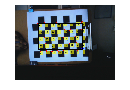

%% Question 1
clear all
close all
% rosinit
sub = rossubscriber('/usb_cam/image_raw');


[scanData,status,statustext] = receive(sub,10);
[scanData2,status,statustext] = receive(sub,10);

I = scanData.readImage;

[imagePoints,boardSize] = detectCheckerboardPoints(I);

% Display detected points.



BoardPoints = boardSize - 1;

ROI = [imagePoints(1,1:2); imagePoints(end,1:2)];

BTMLEFT = [ROI(2,1) ROI(1,2)]; % Bottom Left Corner
TOPRIG = [ROI(1,1) ROI(2,2)];

J = insertText(I,imagePoints,1:size(imagePoints,1));
J = insertMarker(J,imagePoints,'o','Color','red','Size',5);
J = insertMarker(J,ROI,'square','Color','blue','Size',10);

J = insertMarker(J,BTMLEFT,'star','Color','green','Size',10);
J = insertMarker(J,TOPRIG,'star','Color','green','Size',10);

rect = [ROI(2, 1:2), abs(TOPRIG - BTMLEFT)];

imshow(J);
title(sprintf('Detected a %d x %d Checkerboard',boardSize));
figure(1);
rectangle('position', rect);

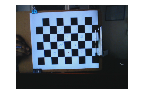


imshow(scanData.readImage);

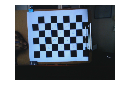

imshow(scanData2.readImage);


%msg = sub.LatestMessage.Data;
% img = rosReadImage(msg);    
% imshow(msg);